# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'kinovaGen3';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "EndEffector_Link"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([0.4 0 0.2])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

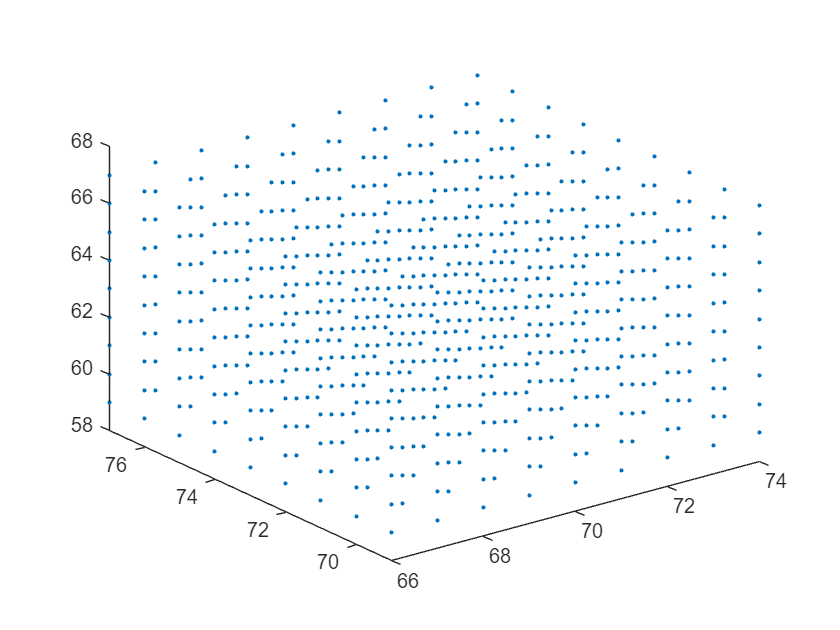

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

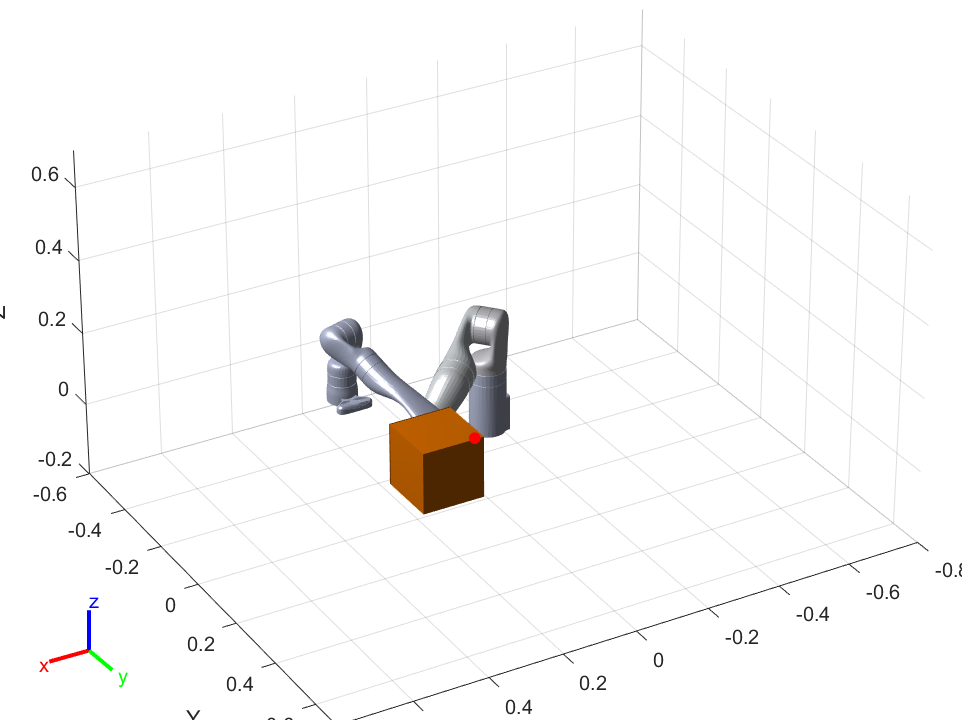

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Qtheta = 65.6693

RAR = 52.9831

Elapsed time is 2.373661 seconds.


Qtheta = 69.3378

RAR = 53.3286

Elapsed time is 2.067164 seconds.


Qtheta = 74.6800

RAR = 53.3254

Elapsed time is 1.365482 seconds.


Qtheta = 76.0935

RAR = 53.4846

Elapsed time is 1.321263 seconds.


Qtheta = 77.4133

RAR = 53.6487

Elapsed time is 1.242769 seconds.


Qtheta = 82.0423

RAR = 53.2728

Elapsed time is 1.246906 seconds.


Qtheta = 83.4087

RAR = 53.4182

Elapsed time is 1.838006 seconds.


Qtheta = 86.5520

RAR = 53.4138

Elapsed time is 2.162305 seconds.


Qtheta = 86.9316

RAR = 53.5761

Elapsed time is 1.924338 seconds.


Qtheta = 92.1280

RAR = 53.7023

Elapsed time is 2.111002 seconds.


Qtheta = 88.3550

RAR = 54.3104

Elapsed time is 1.602203 seconds.


Qtheta = 89.8033

RAR = 54.3670

Elapsed time is 1.235991 seconds.


Qtheta = 88.9532

RAR = 54.5341

Elapsed time is 1.769731 seconds.


Qtheta = 90.7645

RAR = 54.5247

Elapsed time is 1.545819 seconds.


Qtheta = 89.7447

RAR = 54.1402

Elapsed time is 1.238209 seconds.


Qtheta = 90.4097

RAR = 53.9918

Elapsed time is 2.034611 seconds.


Qtheta = 91.5218

RAR = 53.6793

Elapsed time is 1.317000 seconds.


Qtheta = 94.5098

RAR = 53.3974

Elapsed time is 1.241180 seconds.


Qtheta = 93.1413

RAR = 53.2274

Elapsed time is 1.244828 seconds.


Qtheta = 93.8823

RAR = 53.3864

Elapsed time is 1.585908 seconds.


Qtheta = 95.7721

RAR = 53.1445

Elapsed time is 1.877593 seconds.


Qtheta = 96.0301

RAR = 52.8374

Elapsed time is 2.185597 seconds.


Qtheta = 98.3320

RAR = 53.1228

Elapsed time is 2.185767 seconds.


Qtheta = 95.3060

RAR = 53.2085

Elapsed time is 1.321629 seconds.


Qtheta = 95.2392

RAR = 52.8988

Elapsed time is 1.267634 seconds.
STOMP Finished.


isTrajectoryInCollision = logical
   0


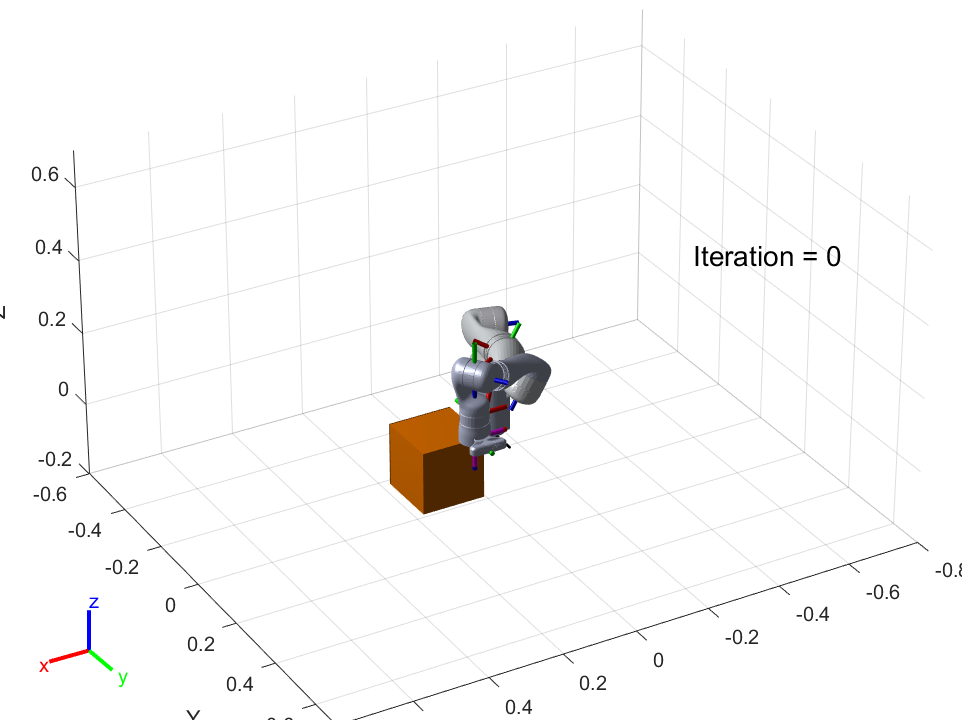

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.